% Prática 1 - Processamento Digital de Sinais

## 1) Geração do sinal

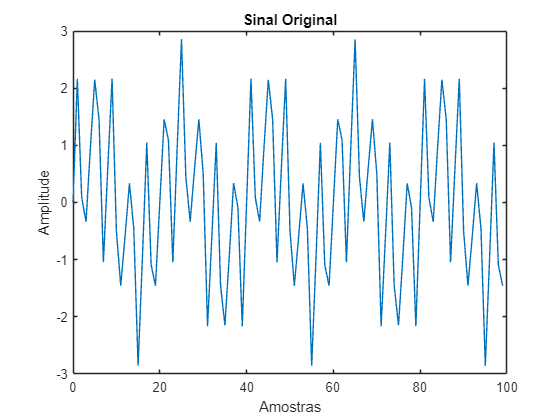

N = 100; % Número de amostras
n = 0:N-1; % Vetor de amostras
frequencias = [0.1*pi, 0.5*pi, 0.75*pi]; % Frequências angulares
amplitudes = [1, 1.5, 0.5]; % Amplitudes

sinal = sum(sin(n'*frequencias).*amplitudes, 2);

figure;
plot(n, sinal);
title('Sinal Original');
xlabel('Amostras');
ylabel('Amplitude');

## 2) Transformada de Fourier do sinal

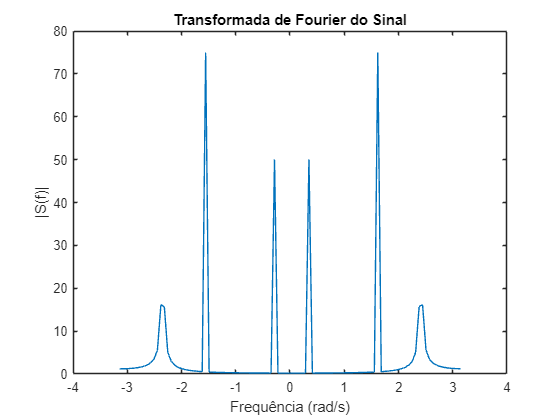


S = fftshift(abs(fft(sinal))); % Módulo da FFT

frequencias_fft = linspace(-pi, pi, N); % Eixo de frequências

figure;
plot(frequencias_fft, S);
title('Transformada de Fourier do Sinal');
xlabel('Frequência (rad/s)');
ylabel('|S(f)|');

## 3) Filtro Butterworth

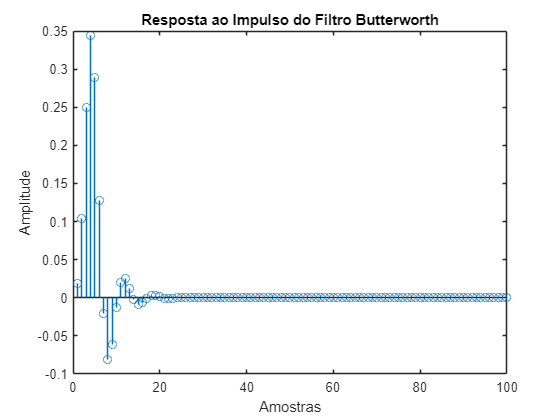

wc = 0.3*pi; % Frequência de corte
ordem = 4; % Ordem do filtro
[b, a] = butter(ordem, wc/pi); % Coeficientes do filtro passa-baixa
impulso = [1, zeros(1, N-1)]; % Resposta ao impulso

resposta_impulso = filter(b, a, impulso);

figure;
stem(resposta_impulso);
title('Resposta ao Impulso do Filtro Butterworth');
xlabel('Amostras');
ylabel('Amplitude');

## 4) Resposta em magnitude do filtro

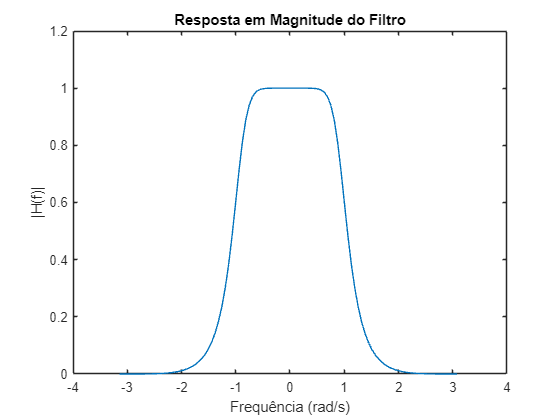

[h, w] = freqz(b, a, N, 'whole'); % Resposta em frequência

figure;
plot(w - pi, abs(fftshift(h))); % Frequências entre -pi e pi
title('Resposta em Magnitude do Filtro');
xlabel('Frequência (rad/s)');
ylabel('|H(f)|');

## 5) Filtragem do sinal

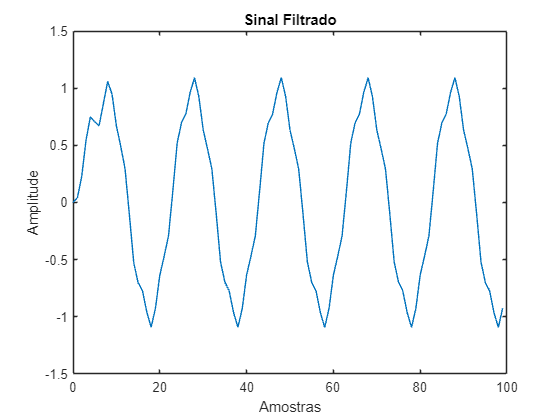

sinal_filtrado = filter(b, a, sinal);

figure;
plot(n, sinal_filtrado);
title('Sinal Filtrado');
xlabel('Amostras');
ylabel('Amplitude');

## 6) Transformada de Fourier do sinal filtrado

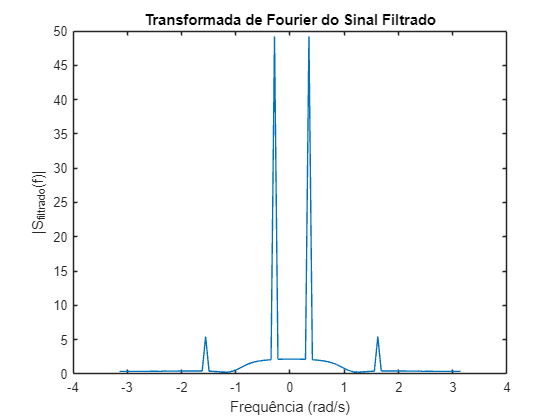

S_filtrado = fftshift(abs(fft(sinal_filtrado))); % Módulo da FFT

figure;
plot(frequencias_fft, S_filtrado);
title('Transformada de Fourier do Sinal Filtrado');
xlabel('Frequência (rad/s)');
ylabel('|S_{filtrado}(f)|');

## 7) Adição de ruído e repetição

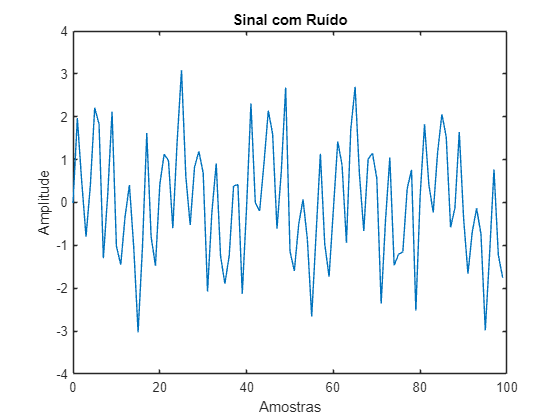

variancia_ruido = 0.1;
ruido = sqrt(variancia_ruido) * randn(1, N); % Ruído branco gaussiano
sinal_ruidoso = sinal + ruido';

% Repetir passo 1 (gráfico do sinal com ruído)
figure;
plot(n, sinal_ruidoso);
title('Sinal com Ruído');
xlabel('Amostras');
ylabel('Amplitude');

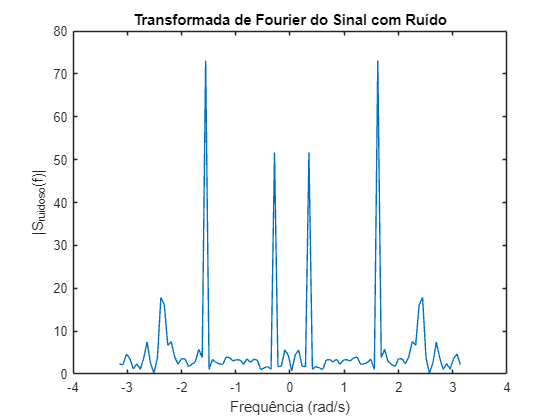

% Repetir passo 2 (Transformada de Fourier do sinal com ruído)
S_ruidoso = fftshift(abs(fft(sinal_ruidoso)));

figure;
plot(frequencias_fft, S_ruidoso);
title('Transformada de Fourier do Sinal com Ruído');
xlabel('Frequência (rad/s)');
ylabel('|S_{ruidoso}(f)|');

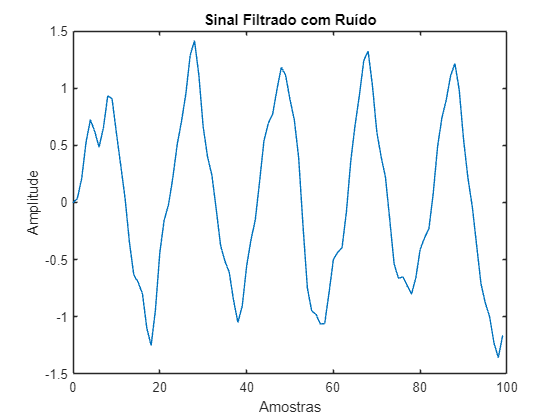

% Repetir passo 5 (Filtrar o sinal com ruído)
sinal_filtrado_ruidoso = filter(b, a, sinal_ruidoso);

figure;
plot(n, sinal_filtrado_ruidoso);
title('Sinal Filtrado com Ruído');
xlabel('Amostras');
ylabel('Amplitude');

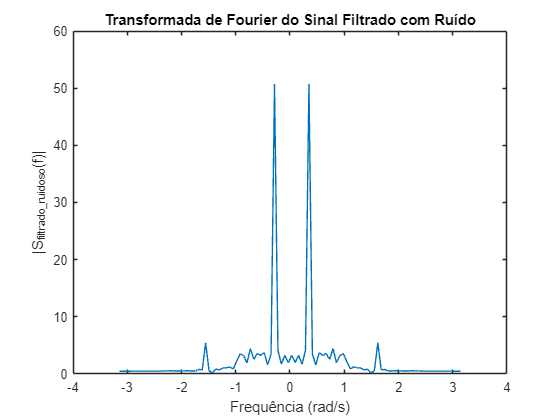

% Repetir passo 6 (Transformada de Fourier do sinal filtrado com ruído)
S_filtrado_ruidoso = fftshift(abs(fft(sinal_filtrado_ruidoso)));

figure;
plot(frequencias_fft, S_filtrado_ruidoso);
title('Transformada de Fourier do Sinal Filtrado com Ruído');
xlabel('Frequência (rad/s)');
ylabel('|S_{filtrado\_ruidoso}(f)|');